clear;
close all;
clc;

## MLC Lab - Quanser Aero Helicopter Control

% Load the parameters
quanser_aero_parameters;
quanser_aero_state_space;
s=tf('s');

% Build the plant
Gunc=ss(A,B,C,D);
Gnom=tf(Gunc);

## 1. Prelimary 

## 1) Find the poles and zeros of the plant

p=eig(minreal(Gnom))

p =   -0.1625 + 1.2982i
  -0.1625 - 1.2982i
   0.0000 + 0.0000i
  -1.0004 + 0.0000i


z=tzero(minreal(Gnom))


z =

  0×1 empty double column vector



    The nominal system has 4 poles and no zeros

     Note that one of the poles is on the origin.

## **2) Bode plot**

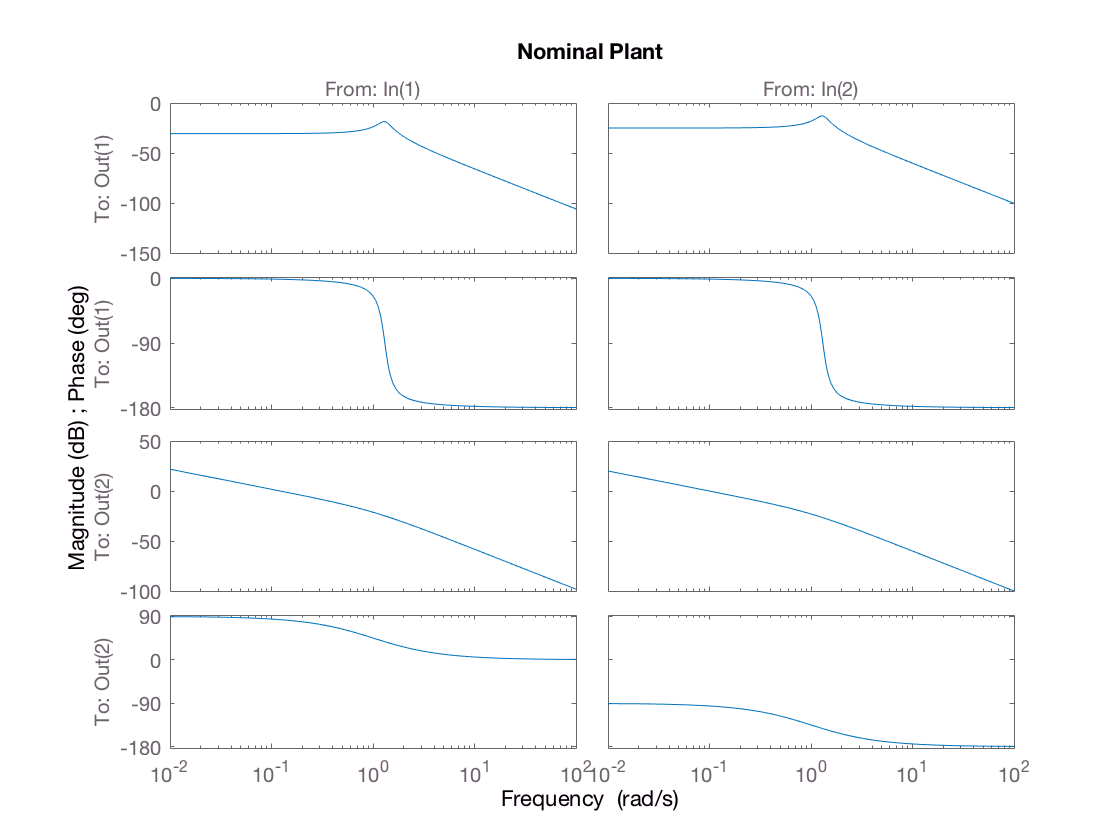

bode(Gnom);
title('Nominal Plant')

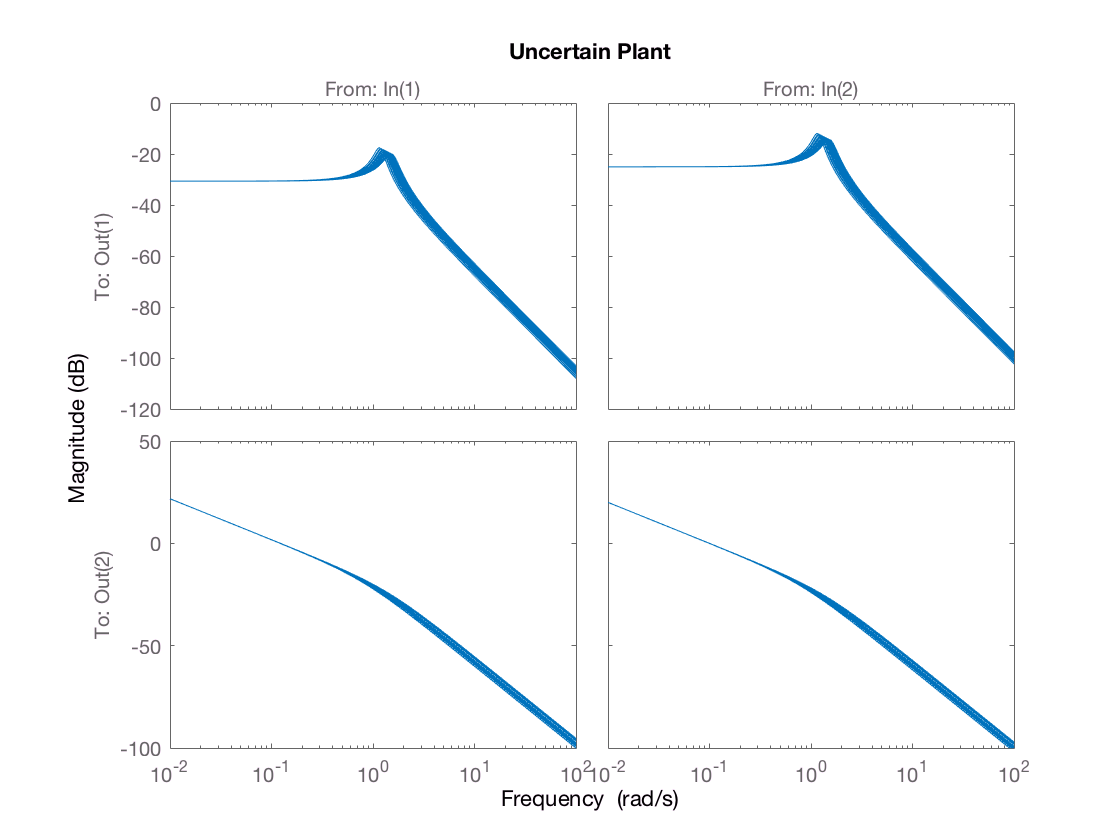

bodemag(Gunc);
title('Uncertain Plant')

    Check the stability margin of the open loop plant

    Note that the loop shape of G(2,1) is not good and will be unstable for simple feedback control

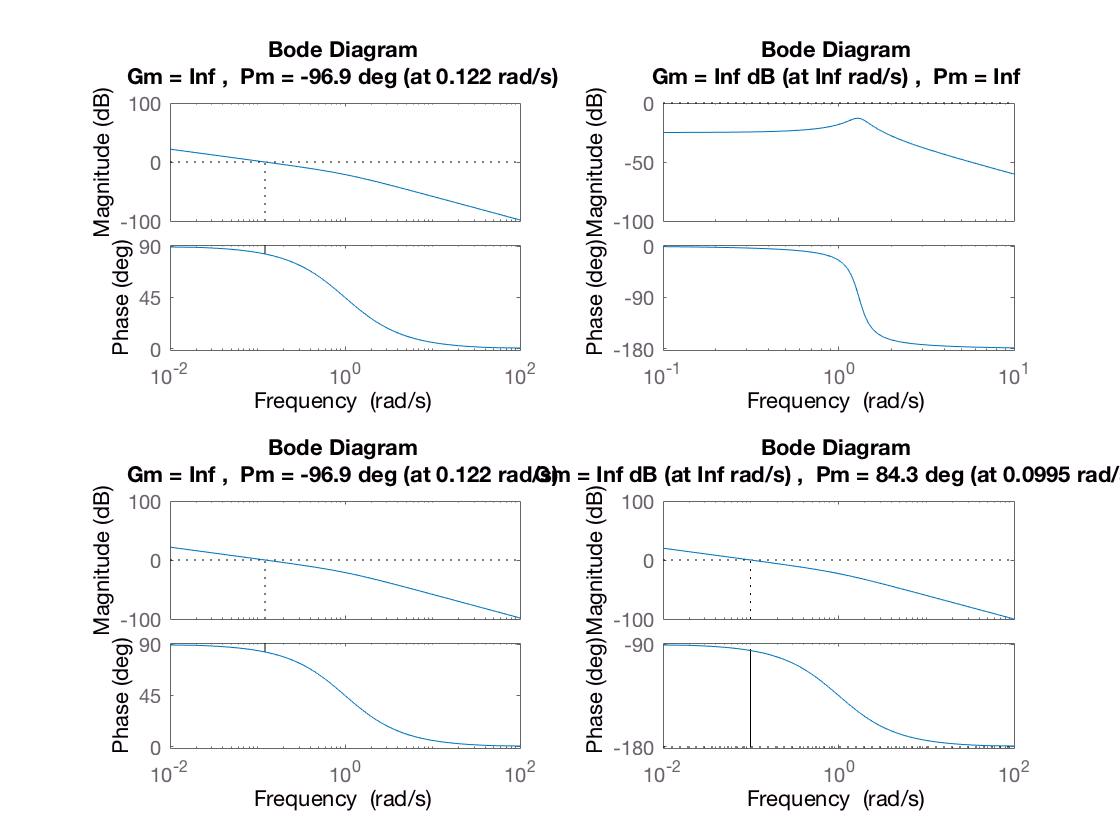

subplot(2,2,1)
margin(Gnom(2,1))
subplot(2,2,2)
margin(Gnom(1,2))
subplot(2,2,3)
margin(Gnom(2,1))
subplot(2,2,4)
margin(Gnom(2,2))

## 3) Simulink model

## 4) Weights/ Uncertainity

    The uncertainty of Jp and Jy has already been included in the uncertain model. Fit a multiplicative uncertainty

    model instead.

% Multiplicative uncertainity Weight
[Gunc_mult,info] = ucover(usample(Gunc,100),Gnom,[4 4],'InputMult');
WI=info.W1;
bodemag(inv(Gnom)*(Gunc_mult-Gnom), WI);

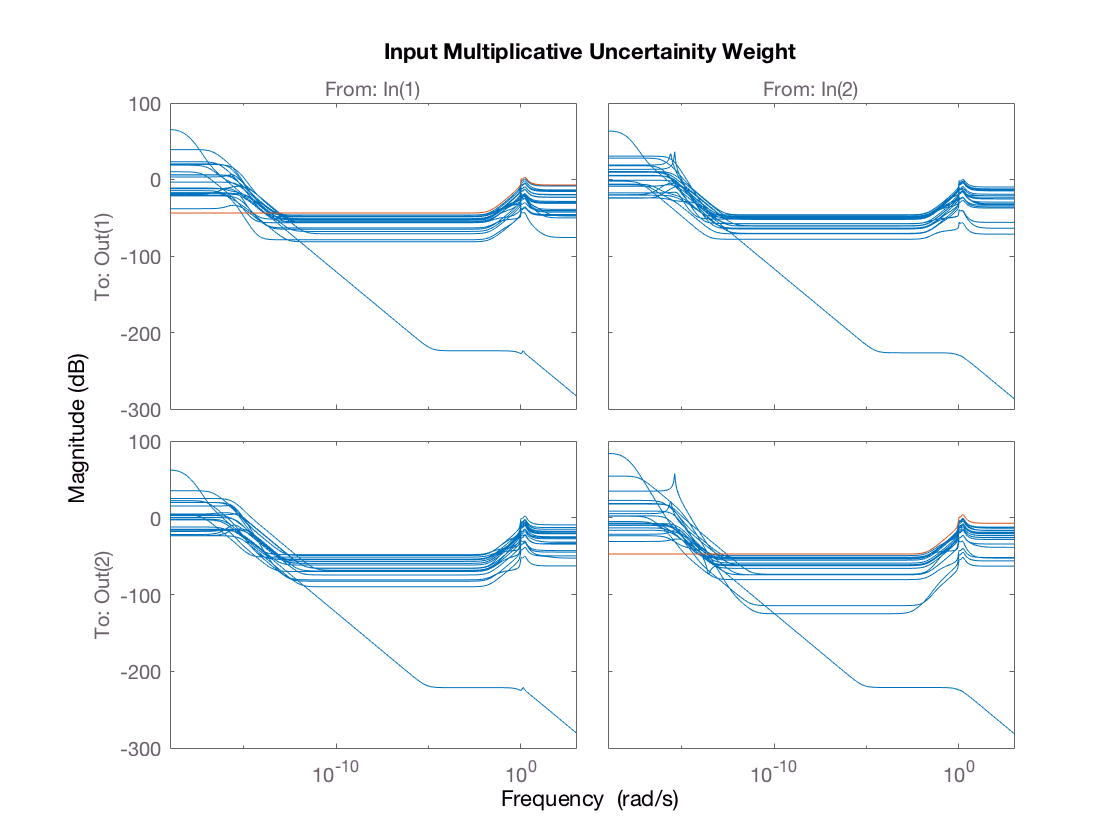

title('Input Multiplicative Uncertainity Weight');

## 2. Loop Shaping 

## 1) Design an inverse-based controller and plot the responses

% Performance Weight
wc=5; % crossover frequency
W_p=makeweight(100,wc,1/3);
Wp=eye(2)*W_p;

% Controller Weight
Wu=inv([25,0;0,25]);

% Uncertainity
D1=ultidyn('D1',[1,1]);
D2=ultidyn('D2',[1,1]);
Del_I=[D1,0;0,D2];


% Loop shape = wc/s;
Ld=wc/s;
% To make proper divide by large pole polynomial twice
% K_inv=(wc/s)*(inv(Gnom))*(1/(s+100)^2);
% K_inv=(wc/s)*(inv(Gnom));
% Or just use loopsyn
[K_inv,CL_inv,GAM_inv]=loopsyn(Gunc,Ld);
L_inv=Gunc*K_inv;
% Sensitivity function
S_inv=inv(eye(2)+L_inv);
T_inv=eye(2)-S_inv;

## 2) Check the RS and RP of our design

% Check RS/RP.
robstabmag_inv=robuststab(S_inv);
mu_stab_inv=1/robstabmag_inv.UpperBound;
fprintf('Mu for RS for Inverse based controller is %f\n',mu_stab_inv);

Mu for RS for Inverse based controller is 0.000000


robperfmag_inv=robustperf(S_inv);
mu_perf_inv=1/robperfmag_inv.UpperBound;
fprintf('Mu for RP for Inverse based controller is %f\n',mu_perf_inv);

Mu for RP for Inverse based controller is 1.001822


    Run the simulation on 10 different values of $\triangle$

% Simulation
K=K_inv;
% sim('MLC_Aero_Simulink')
figure;
plot(simout.time,simout.signals.values);

Undefined variable "simout" or class "simout.time".

title('Output using loopsyn controller');
figure;
plot(simcontrol.time,simcontrol.signals.values);
title('Control usage using loopsyn controller');

## 3) Implement controller on hardware and compare results with simulation

## 4) Run hardware simulation for uncertain samples

## 3. LQG Design


% Divide performance weight by large pole ot make it proper. LQG does not
% like improper weight.
W_p_LQG=Wp*(1/(s+100));

% Noise Varaince from Manual
QXU = blkdiag(diag([200,150,100,200]),50,50);
QWV = blkdiag(10*eye(4),1*eye(2));  
K_LQG = -lqg(Gunc.NominalValue,QXU,QWV);
% Sensitivity function
S_LQG=eye(2)/(eye(2)+Gunc*K_LQG);
T_LQG=eye(2)-S_LQG;

% Check RS/RP
robstabmag_LQG=robuststab(S_LQG);
mu_stab_LQG=1/robstabmag_LQG.UpperBound;
fprintf('Mu for RS for LQG controller is %f\n',mu_stab_LQG);
robperfmag_LQG=robustperf(S_LQG);
mu_perf_LQG=1/robperfmag_LQG.UpperBound;
fprintf('Mu for RP for LQG controller is %f\n',mu_perf_LQG);

% Simulation
K=K_LQG;
sim('MLC_Aero_model')
figure;
plot(simout.time,simout.signals.values);
title('Output using LQG controller');
figure;
plot(simcontrol.time,simcontrol.signals.values);
title('Control usage using LQG controller');

## 4. $H_2$ Optimal Control

% Divide performance weight by large pole ot make it proper. H2syn does not
% like improper weight.
Wp_2=Wp*(1/(s+100));

% Build Generalized plant using sysic
systemnames = 'WI Wu Wp_2 Gnom';
inputvar = '[ud{2};w{2};u{2}]';
outputvar = '[WI;Wu;Wp_2;-w-Gnom]';
input_to_Gnom = '[u+ud]';
input_to_WI = '[u]';
input_to_Wp_2 = '[w+Gnom]';
input_to_Wu = '[u]';
cleanupsysic = 'yes';  
PP2 = sysic;

[K_2, CL_2,GAM_2]=h2syn(PP2,2,2);

% Sensitivity function
S_2=eye(2)/(eye(2)+Gunc*K_2);
T_2=eye(2)-S_2;

N_2=lft(PP2,K_2);
% Check RS/RP
robstabmag_LQG=robuststab(N_2);
mu_stab_2=1/robstabmag_LQG.UpperBound;
fprintf('Mu for RS for H2syn controller is %f\n',mu_stab_2);
robperfmag_LQG=robustperf(N_2);
mu_perf_2=1/robperfmag_LQG.UpperBound;
fprintf('Mu for RP for H2syn controller is %f\n',mu_perf_2);

% Simulation
K=K_2;
sim('MLC_Aero_model')
figure;
plot(simout.time,simout.signals.values);
title('Output using H2syn controller');
figure;
plot(simcontrol.time,simcontrol.signals.values);
title('Control usage using H2syn controller');

## H-inf

fprintf('H-inf Controller\n');
fprintf('=================================================\n');

% Build Generalized plant using sysic
systemnames = 'WI Wu Wp Gnom';
inputvar = '[ud{2};w{2};u{2}]';
outputvar = '[WI;Wu;Wp;-w-Gnom]';
input_to_Gnom = '[u+ud]';
input_to_WI = '[u]';
input_to_Wp = '[w+Gnom]';
input_to_Wu = '[u]';
cleanupsysic = 'yes';  
PP = sysic;
[K_INF, CL_INF,GAM_INF]=hinfsyn(PP,2,2);

% Sensitivity Function
S_INF=inv(eye(2)+Gunc*K_INF);
T_INF=eye(2)-S_INF;
N_INF=lft(PP,K_INF);
% Check RS/RP
STABMARG= robuststab(N_INF);
mu_stabinf = 1/STABMARG.LowerBound;
fprintf('The mu for RS using hinfsyn is: %f\n',mu_stabinf);
STABMARG= robustperf(N_INF);
mu_perfinf = 1/STABMARG.LowerBound;
fprintf('The mu for RP using hinfsyn is: %f\n',mu_perfinf);

% Simulation
K=K_INF;
sim('MLC_Aero_model')
figure;
plot(simout.time,simout.signals.values);
title('Output using Hinfsyn controller');
figure;
plot(simcontrol.time,simcontrol.signals.values);
title('Control usage using hinfsyn controller');

## Mu-Synthesis

fprintf('Mu Synthesis Controller Controller\n');
fprintf('=================================================\n');

% Define Plant using sysic
% Build Generalized plant using sysic
systemnames = 'Wu Wp Gunc';
inputvar = '[w{2};u{2}]';
outputvar = '[Wu;Wp;-w-Gunc]';
input_to_Gunc = '[u]';
input_to_Wp = '[w+Gunc]';
input_to_Wu = '[u]';
cleanupsysic = 'yes';  
PMU = sysic;

[K_MU, CL_MU,GAM_MU]=dksyn(PMU,2,2);
S_MU=inv(eye(2)+Gunc*K_MU);
T_MU=eye(2)-S_MU;

N_MU=lft(PMU,K_MU);
% Check RS/RP
STABMARG= robuststab(N_MU);
mu_stabMU = 1/STABMARG.LowerBound;
fprintf('The mu for RS using dksyn is: %f\n',mu_stabMU);
% Use robustperf to compute mu
STABMARG= robustperf(N_MU);
mu_perfMU = 1/STABMARG.LowerBound;
fprintf('The mu for RP using dksyn is: %f\n',mu_perfMU);

% Simulation
K=K_MU;
sim('MLC_Aero_model')
figure;
plot(simout.time,simout.signals.values);
title('Output using dksyn controller');
figure;
plot(simcontrol.time,simcontrol.signals.values);
title('Control usage using dksyn controller');

## Bode magnitude plot of all sensitivity functions:

bodemag(S_inv,S_LQG,S_2,S_INF,S_MU);
title('All Sensitivity Function plots');
legend('Loopsyn','LQG','H2syn','H-infsyn','dksyn');

## Hinf Loop shaping

## Testing

sim('MLC_Aero_model');

## End of Problem